## Cykly spalovacích motorů příklady

 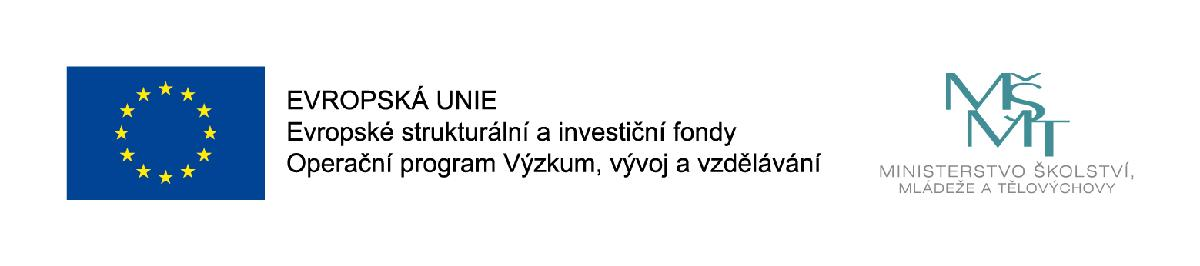

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

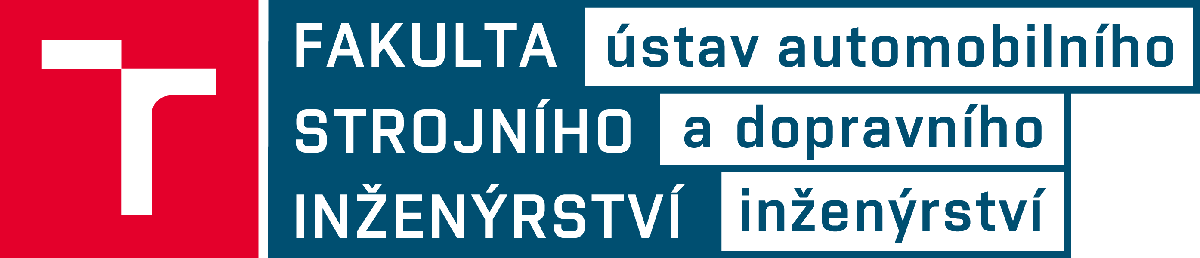

Pracovni latkou motoru s kombinovanym privodem tepla je vzduch (vznětový motor). Určete stavové veličiny v charakteristických bodech cyklu, přivedená tepla, odvedená tepla, získanou praci, výkon a termickou účinnost?.

clear;
clc;
n_valcu = 4;        % Počet válců
D = 86.0;           % [mm] Vrtání
Z = 80.0;           % [mm] Zdvih
Eps = 18;           % [] Kompresní poměr
AF = 14.5;          % [-]  Stechiometrický poměr vrduch/palivo
Lambda = 1.2;       % [-] Součinitel přebytku vzduchu
Hu = 43;            % [MJ/kg] Výhřevnost paliva/nafty
p1hPa = 950;        % [hPa] Tlak v sání
t1 = 29;            % [°C] teplota vzduchu
p3MPa = 9;          % [MPa] Maximální tlak
r_vzduch = 287.04;  % [J/kgK] Měrná plynová konstanta
kapa_vzduch = 1.41; % [ ]
n_otacky = 4200;    % [1/min] Otáčky motoru

Rozměrry motoru

Vz = mm2m(Z)*pi*mm2m(D)^2/4.0

Vz = 4.6470e-04

m32l(Vz)

ans = 0.4647

Vk = Vz/(Eps-1)

Vk = 2.7336e-05

V1 = Vz + Vk;
V2 = Vk;

Vlastnosti plynů

cp_vzduch = kapa_vzduch/ (kapa_vzduch-1)*r_vzduch;
cv_vzduch = cp_vzduch - r_vzduch;

Hmotnosti

p1 = hPa2Pa(p1hPa);
T1 = C2K(t1);
m1 = p1*V1/(r_vzduch * T1);
mv = m1

mv = 5.3896e-04

mp = mv/(Lambda * AF)

mp = 3.0975e-05

m2 = mv + mp;

Bod 2

p2 = p1 * Eps^kapa_vzduch

p2 = 5.5932e+06

T2 = p2 * V2 / (r_vzduch * m1)

T2 = 988.2898

Bod 2 po vstříknutí paliva

p2p = m2 * r_vzduch * T2 / V2;

Bod 3

Qh = Hu * mp * 10^6

Qh = 1.3319e+03

 V3 = V2;
p3 = MPa2Pa(p3MPa)

p3 = 9000000

T3 = p3 * V3 / (r_vzduch * m2)

T3 = 1.5038e+03

Qh1 = m2 * cp_vzduch * (T3 - T2)

Qh1 = 290.0498

Qh2 = Qh - Qh1

Qh2 = 1.0419e+03

Bod 4

T4=Qh2 / (cp_vzduch * m2) + T3

T4 = 3.3557e+03

p4 = p3;
V4 = V3 * T4 / T3;

Bod 5

V5 = V1;
p5 = p4 * (V4 / V1)^kapa_vzduch;
T5 = T1 * (p5 / p1)

T5 = 1.5077e+03

fprintf('p_1 : %.3f MPa  T_1 : %.1f K V_1 : %.3f l\n',p1/10^6,T1, V1*1000);

p_1 : 0.095 MPa  T_1 : 302.1 K V_1 : 0.492 l


fprintf('p_2 : %.3f MPa  T_2 : %.1f K V_2 : %.3f l\n',p2/10^6,T2, V2*1000);

p_2 : 5.593 MPa  T_2 : 988.3 K V_2 : 0.027 l


fprintf('p_3 : %.3f MPa  T_3 : %.1f K V_3 : %.3f l\n',p3/10^6,T3, V3*1000);

p_3 : 9.000 MPa  T_3 : 1503.8 K V_3 : 0.027 l


fprintf('p_4 : %.3f MPa  T_4 : %.1f K V_4 : %.3f l\n',p4/10^6,T4, V4*1000);

p_4 : 9.000 MPa  T_4 : 3355.7 K V_4 : 0.061 l


fprintf('p_5 : %.3f MPa  T_5 : %.1f K V_5 : %.3f l\n',p5/10^6,T5, V5*1000);

p_5 : 0.474 MPa  T_5 : 1507.7 K V_5 : 0.492 l


Integrální veličiny

Qc =  m2 * cv_vzduch * (T1-T5)

Qc = -481.0199

Ao = Qh + Qc

Ao = 850.9001

fprintf('Přivedené teplo : %.3f J\n',Qh);

Přivedené teplo : 1331.920 J


fprintf('Odvedené teplo  : %.3f J\n',Qc);

Odvedené teplo  : -481.020 J


fprintf('Práce cyklu : %.3f J\n',Ao);

Práce cyklu : 850.900 J


pis = Ao/Vz;
Etat = Ao / Qh;
fprintf('Střední teoretický tlak : %.3f MPa\n',pis/10^6);

Střední teoretický tlak : 1.831 MPa


fprintf('Termická účinnost : %.1f %\n',Etat*100);

Termická účinnost : 63.9 

P = n_valcu * Ao * n_otacky / 60 / 2;
Pkw = P/1000;
fprintf('Výkon motoru : %.1f kW\n',Pkw);

Výkon motoru : 119.1 kW


###  Grafy

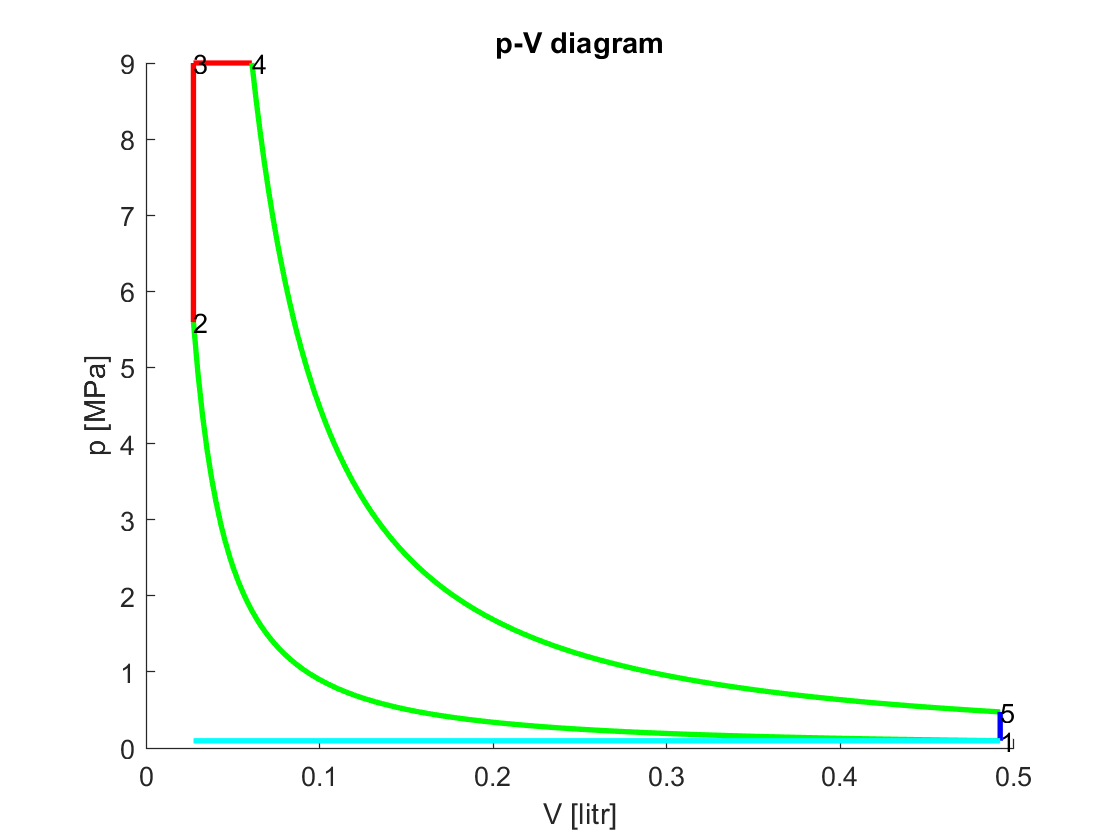

vv1 = linspace(V1,V2,180);
pv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);

for i=2:180
  pv1(i) = p1*V1^kapa_vzduch/vv1(i)^kapa_vzduch;
  Tv1(i) = pv1(i) * vv1(i) / (m1 * r_vzduch);
  Sv1(i)=m1*cp_vzduch*log(Tv1(i)) - m1*r_vzduch*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
vv1(1) = V1;
vv1(180) = V2;
Tv1(1) = pv1(1) * vv1(1) / (m1 * r_vzduch);
Sv1(1)=m1*cp_vzduch*log(Tv1(1))-m1*r_vzduch*log(pv1(1));

pv2 = linspace(p2,p3,180);
vv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  vv2(i)= V2;
  Tv2(i) = pv2(i) * vv2(i) / (m1 * r_vzduch);
  Sv2(i)=m1 * cp_vzduch*log(Tv2(i))-m1*r_vzduch*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
vv2(1) = V2;
vv2(180) = V3;
Tv2(1) = pv2(1) * vv2(1) / (m1 * r_vzduch);
Sv2(1)=m1 * cp_vzduch*log(Tv2(1))-m1 * r_vzduch * log(pv2(1));

vv3 = linspace(V3,V4,180);
pv3 = zeros([1,180]);
for i=2:180
  pv3(i)= p3;
  Tv3(i) = pv3(i) * vv3(i) / (m1 * r_vzduch);
  Sv3(i)=m1 * cp_vzduch*log(Tv3(i))-m1 * r_vzduch * log(pv3(i));  
end
pv3(1) = p3;
pv3(180) = p4;
vv3(1) = V3;
vv3(180) = V4;
Tv3(1) = pv3(1) * vv3(1) / (m1 * r_vzduch) ;
Sv3(1)=m1 * cp_vzduch*log(Tv3(1))-m1 * r_vzduch*log(pv3(1));  

vv4 = linspace(V4,V5,180);
pv4 = zeros([1,180]);
for i=2:180
  pv4(i)=p4*V4^kapa_vzduch/vv4(i)^kapa_vzduch;
  Tv4(i) = pv4(i) * vv4(i) / (m1 * r_vzduch);
  Sv4(i)=m1 * cp_vzduch * log(Tv4(i))-m1 * r_vzduch*log(pv4(i));    
end
pv4(1) = p4;
pv4(180) = p5;
vv4(1) = V4;
vv4(180) = V5;
Tv4(1) = pv4(1) * vv4(1) / (m1 * r_vzduch);
Sv4(1)=m1 * cp_vzduch*log(Tv4(1))-m1 * r_vzduch*log(pv4(1));    

pv5 = linspace(p5,p1,180);
vv5 = zeros([1,180]);
Tv5 = zeros([1,180]);
Sv5 = zeros([1,180]);
for i=2:180
  vv5(i)= V5;
  Tv5(i) = pv5(i) * vv5(i) / (m1 * r_vzduch) ;
  Sv5(i)=m1 * cp_vzduch*log(Tv5(i))-m1 * r_vzduch*log(pv5(i));
end
pv5(1) = p5;
pv5(180) = p1;
vv5(1) = V5;
vv5(180) = V1;
Tv5(1) = pv5(1) * vv5(1) / (m1 * r_vzduch);
Sv5(1)=m1 *cp_vzduch*log(Tv5(1))-m1 * r_vzduch*log(pv5(1));

vv0 = linspace(V1,V2,180);
pv0 = zeros([1,180]);
for i=2:180
  pv0(i)= p1;
end
pv0(1) = p1;
pv0(180) = p1;
vv0(1) = V1;
vv0(180) = V2;

figure;
% název grafu a popisy os
title('p-V diagram')
xlabel('V [litr]')
ylabel('p [MPa]')   
hold on;
plot(m32l(vv1),Pa2MPa(pv1),'g-','linewidth',2);
plot(m32l(vv2),Pa2MPa(pv2),'r-','linewidth',2);
plot(m32l(vv3),Pa2MPa(pv3),'r-','linewidth',2);
plot(m32l(vv4),Pa2MPa(pv4),'g-','linewidth',2);
plot(m32l(vv5),Pa2MPa(pv5),'b-','linewidth',2);
plot(m32l(vv0),Pa2MPa(pv0),'c-','linewidth',2);
hold off;
% popis bodů diagramu
text(vv1(1)*10^3,(pv1(1)-0.2)/10^6,'1');
text(vv2(1)*10^3,(pv2(1)-0.2)/10^6,'2');
text(vv3(1)*10^3,(pv3(1)+0.2)/10^6,'3');
text(vv4(1)*10^3,(pv4(1)+0.2)/10^6,'4');
text(vv5(1)*10^3,(pv5(1)+0.2)/10^6,'5');

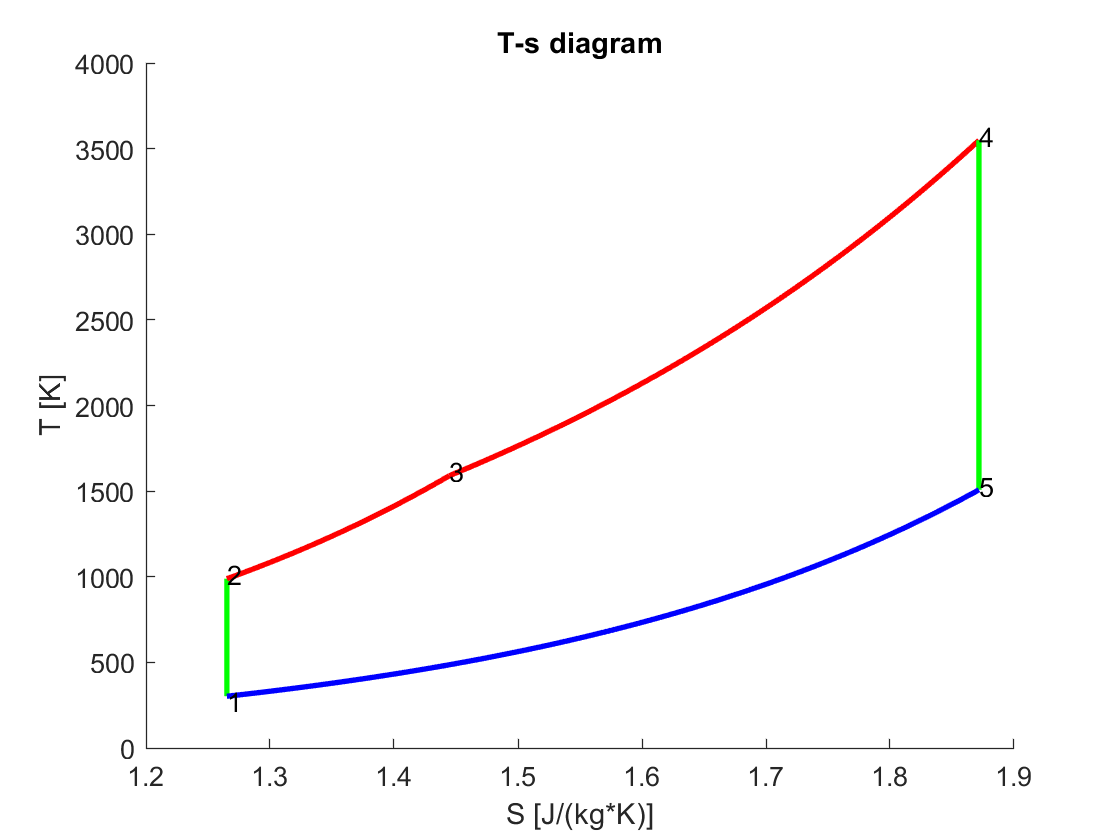


figure;
% název grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]')                      % ^\circC
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'r-','linewidth',2);
plot(Sv4,Tv4,'g-','linewidth',2);
plot(Sv5,Tv5,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
text(Sv5(1),Tv5(1)+25,'5');

### 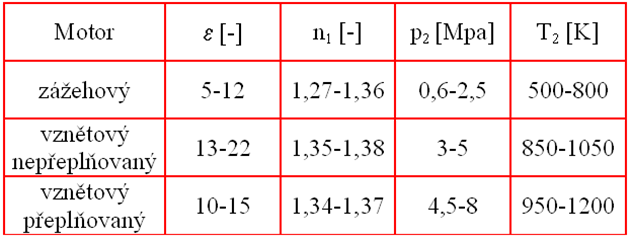

### Modifikace příkladu

Předchozí příklad zmodifikujte tak, aby zahrnoval i vlastnosti spalin a místo adiabat obsahoval polytropy.


T6 = 1450 / Eps + 1092/Lambda + 8.4 * n_otacky/60 - 494

T6 = 1.0846e+03

p0 = p1

p0 = 95000

p6 = p0*(1+33E-4*n_otacky/60)

p6 = 1.1694e+05

n_exp = 1.22+2.167/(n_otacky/60)

n_exp = 1.2510

n_kom = 1.41-1.667/(n_otacky/60)

n_kom = 1.3862

C = 0.86

C = 0.8600

H = 0.013

H = 0.0130

O = 0.005

O = 0.0050

S = 0.005

S = 0.0050

deltaTsani = 12;

Sigma = 1+(3/C)*(H+(S-O)/8)

Sigma = 1.0453

Hu = 33913*C+102995*H-10886*(O-S)

Hu = 3.0504e+04


T0 = 300;
EtaPln = 0.91;
EtaMech = 0.7;
EtaCh = 0.92;
EtaPl = 0.9;
T1 = (p1 *T0 *T5)/ (p5*T0+(Eps-1)*EtaPln*T6)

T1 = 302.1144

p1 = p6/Eps+p0*((Eps-1)*EtaPln*(T0+deltaTsani))/(Eps*T0)

p1 = 9.1410e+04

T1 = p1*Eps*T0/(p0*(Eps-1)*EtaPln+p6*T0/T6)

T1 = 328.6384

%p1 = (Eps-1)/Eps * T0/T0*p0*EtaPln+1/Eps*p6

### Lokální funkce 

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převádí hektopascaly na Pascaly

function [Pa] = MPa2Pa(MPa)
Pa = MPa*10^6;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod litrů

function [l] = m32l(m3)
l = m3 /0.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [m] = mm2m(mm)
m = mm / 1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end